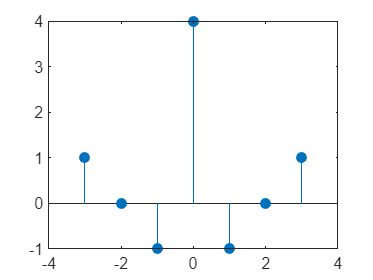

%CCC example%
tic
clear all
clc
close all

C_1 = [1 1 -1 1];
C_2 = [1 -1 -1 -1];


%aperiodic autocorrelation%
[a_auto,lags] = xcorr(C_1); 

[a_auto_2,lags] = xcorr(C_2);

c_plus = a_auto + a_auto_2;

stem(lags,a_auto,"filled");

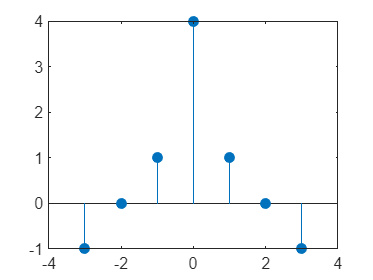

stem(lags,a_auto_2,"filled");

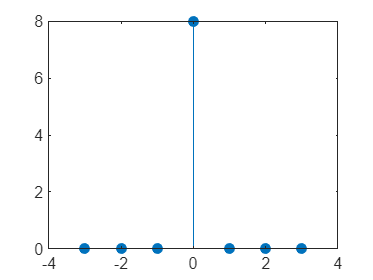

stem(lags,c_plus,"filled");

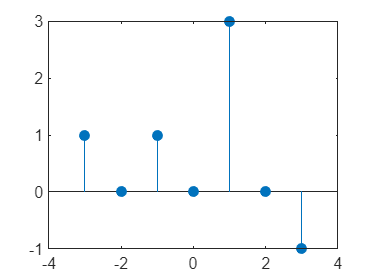

%aperiodic crosscorrelation%

C_1_bar = [1 1 1 -1];
C_2_bar = [1 -1 1 1];

[a_cross,lags] = xcorr(C_1_bar,C_1);

[a_cross_2,lags] = xcorr(C_2_bar,C_2);

c_plus_cross = a_cross + a_cross_2;

stem(lags,a_cross,"filled");

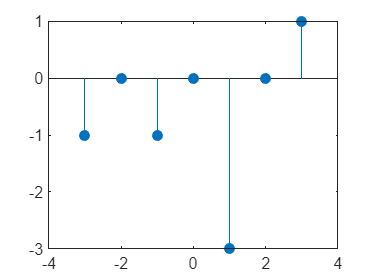

stem(lags,a_cross_2,"filled");

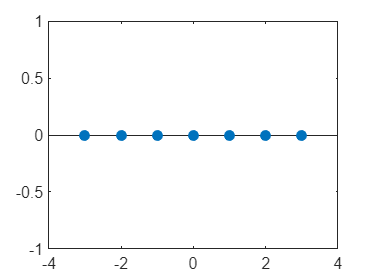

stem(lags,c_plus_cross,"filled");
ylim([-1,1]);

toc

Elapsed time is 1.627035 seconds.
